clear all; clc;
% cd(fileparts(which(mfilename)));  % In a .m file uncomment this
cd(fileparts(matlab.desktop.editor.getActiveFilename)); % In a .mlx file uncomment this

# Example: Double Pendulum

Develop a Kalman filter to track the state of the typical particle Double Pendulum. There is no friction. Sensor is a gyro in y ($\omega_y$) and 2 axis accelerometers ($a_x$, $a_z$) on the second pendulum tip with axes along directions $1'$ and $3'$:


$$\mathbf{z}=\left[\begin{array}{c}\omega_y(\mathbf{x},\mathbf{\dot{\mathbf{x}}}) \\ a_x(\mathbf{x},\mathbf{\dot{\mathbf{x}}})\\ a_z(\mathbf{x},\mathbf{\dot{\mathbf{x}}})\end{array}\right]$$


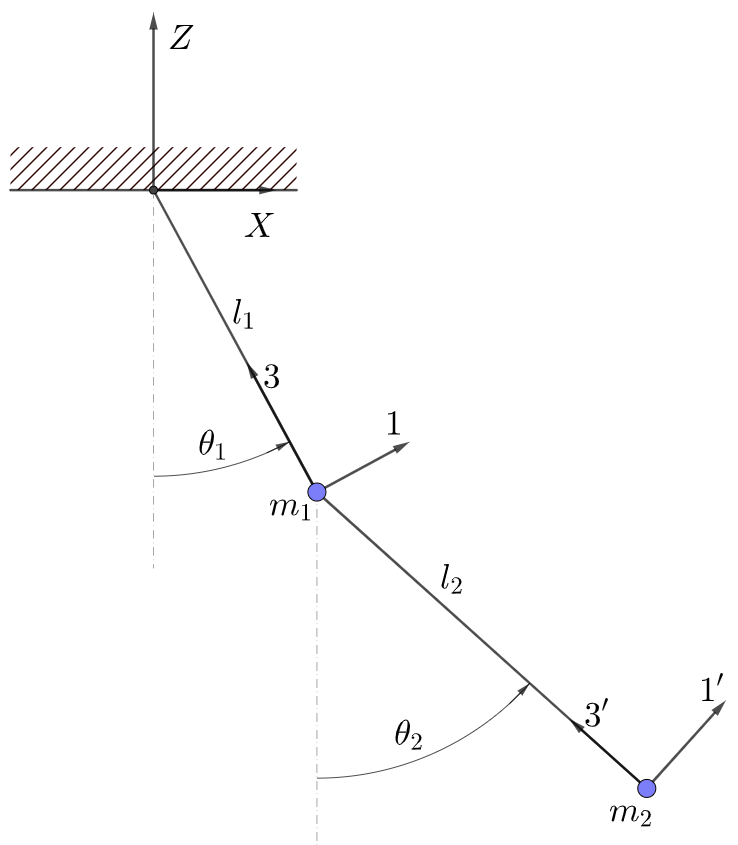

Determine transition process equations & sensor equations, and the required Jacobians.

# Solution:

Parameters and initial state definition

global t t_0 t_end Delta_t
global mu_x Sigma2_x
global u_meas z_meas
global sigma_u_actual sigma_z_actual x_actual x_actual_0 u_actual_func rng_status seed
global x_string u_string z_string
global param


Define handle to function determining the actual input

u_actual_func = @(t) my_u_actual_func(t);

Seed to get repeatable results between runs (particularly important for ML estimation)

seed=1789; rng(seed);

Error using load
'lsshaft_IMU_series_turb_noisy.mat' is not found in the current folder or on the MATLAB path, but exists in:
    /home/jros/Sync/Docencia/2021-2022/ISD/Bitacora/Gitted_IEKF_Examples/HAWT_Azimuth

Change the MATLAB current folder or add its folder to the MATLAB path.

rng_status=rng;

Set initial time $t_0$, sampling frequency $\Delta t$ and final simulation time $t_{end}$

% Set Initial time
%%---Edit_Begin
t_0=0;         %s
Delta_t=0.001; %s
t_end=50;      %s

Define model parameters

m1=1;         %kg
m2=1;         %kg
l1=1;         %m
l2=1;         %m
g=10;         %m/s^2
param=[m1 m2 l1 l2 g Delta_t]' % as is from main_symbolic_EKF.m

Set deterministic true/actual system Initial state $\mathbf{x}_0^{tr}$

theta1_0=pi/6      %rad
dtheta1_0=0        %rad/s
theta2_0=pi/6      %rad
dtheta2_0=0        %rad/s
q_0=[theta1_0,theta2_0]'
dq_0=[dtheta1_0,dtheta2_0]'
x_actual_0=[q_0;dq_0]

Filter Initial state and variance $\mu_{x_0}$, $\sigma_{x_0}^2$, estimated from limits in historical meassurements

sigma_theta1_0=pi/2  % rad no idea at all
sigma_dtheta1_0=0.1  % rad/s no idea at all
sigma_theta2_0=pi/2  % rad no idea at all
sigma_dtheta2_0=0.1  % rad/s no idea at all
sigma_x_0= [sigma_theta1_0,sigma_dtheta1_0,sigma_theta2_0,sigma_dtheta2_0]';

mu_x_0 = x_actual_0+sigma_x_0;
Sigma2_x_0 = diag(sigma_x_0.^2); % assumed diagonal @ t=t_0

Model equation error variance $\sigma^2_{u_{k}}$ and $\sigma^2_{w_k}$

n_u=size(u_actual_func(t_0),1);
sigma_u_actual=zeros(n_u,1);
sigma_u=zeros(n_u,1); %input meas. cov. assumed diagonal


Our Euler discretization assumes $\mathbf{q}_{k+1}=\mathbf{q}_{k}+\frac{1}{1!}\dot{\mathbf{q}}_{k}\Delta t$ and $\dot{\mathbf{q}}_{k+1}=\dot{\mathbf{q}}_{k}+\frac{1}{1!}\ddot{\mathbf{q}}(\mathbf{q}_k,\dot{\mathbf{q}}_k,t_k)\Delta t$ and therefore the errors in discterization can be stimated to be of the order of $\frac{1}{2!}\ddot{\mathbf{q}}(\mathbf{q}_k,\dot{\mathbf{q}}_k,t_k)(\Delta t)^2$ and $\frac{1}{2!}\dddot{\mathbf{q}}(\mathbf{q}_k,\dot{\mathbf{q}}_k,t_k)(\Delta t)^2$ at the level of coordinates and generalized velocities respectively.

% max_error_discr=[1/2*1,1/2*1,1/2*1,1/2*1]'*Delta_t^2;
max_error_discr=[2.58418e-06, 3.025e-06, 1.08183e-05, 2.12142e-05]'
sigma_discr=max_error_discr; %discr. err. cov. assumed diagonal

Parameters for other noise sources in process equation $\mathbf{w}_{k}$.  Process equation error std $\mathbf{\sigma}_{\mathbf{w}_{k}}$.

n_x=size(x_actual_0,1);
sigma_w_x=zeros([n_x,1]);

Sensor equation error std $\mathbf{\sigma}_{\mathbf{z}_{k+1}}$, and input sensor measurement error std $\mathbf{\sigma}_{\mathbf{u}_{k}}$ can be given based on the specification sheet of the sensors used to measure $\mathbf{z}$ and $\mathbf{u}$ and are used to tune the filter (use a better value if your have one available). $\mathbf{\sigma}_{\mathbf{z}_{k+1}}^{tr}$ and $\mathbf{\sigma}_{\mathbf{u}_{k}}^{tr}$ are the ***actual*** values of the error std for the sensors used to measure $\mathbf{z}$ and $\mathbf{u}$.

sigma_gyroy_actual=0.1;%rad/s
sigma_gyroy_spec=sigma_gyroy_actual;
sigma_accx_actual=0.1;%m/s^2
sigma_accx_spec=sigma_accx_actual;
sigma_accz_actual=0.1;%m/s^2
sigma_accz_spec=sigma_accz_actual;

sigma_z_actual=[sigma_gyroy_actual,sigma_accx_actual,sigma_accz_actual]';
sigma_z=[sigma_gyroy_spec,sigma_accx_spec,sigma_accz_spec]';

Parameters for other noise sources in sensor equation $\mathbf{v}_{k+1}$. Sensor equation error std $\mathbf{\sigma}_{\mathbf{v}_{k+1}}$.

n_z=size(sigma_z_actual,1);
sigma_v_x=zeros(n_z,1);

t=t_0;
x_actual=x_actual_0
mu_x=mu_x_0;
Sigma2_x = diag(sigma_x_0.^2);

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Set variables to datalog

datalogging_string={'t';'x_actual';'mu_x';'u_actual';'u_meas';'z_actual';'z_meas';'sigma_x'};

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Observability

Linear observability near the end of the simulation

u_meas=get_u(); z_meas=get_z();
f_x_=f_x(mu_x,u_meas,t,param);
h_x_=h_x(mu_x,u_meas,t,param);
 
OB=obsv(f_x_,h_x_)
rank(OB)
size(OB) 

Nonlinear observability near the end of the simulation

load_datalogging('sol.dat', datalogging_string);

Nonlinear observabilty matrix must be bigger (more rows) than the linear one. So 5 time steps must suffice ( $5 \times 2=10>8$ )

k=length(t_series)-5;

OB=[h_x(x_actual_series(k,:)',u_meas_series(k,:)',t_series(k,:),param)
    h_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)
    h_x(x_actual_series(k+4,:)',u_meas_series(k+4,:)',t_series(k+4,:),param)*f_x(x_actual_series(k+4,:)',u_meas_series(k+4,:)',t_series(k+4,:),param)*f_x(x_actual_series(k+3,:)',u_meas_series(k+3,:)',t_series(k+3,:),param)*f_x(x_actual_series(k+2,:)',u_meas_series(k+2,:)',t_series(k+2,:),param)*f_x(x_actual_series(k+1,:)',u_meas_series(k+1,:)',t_series(k+1,:),param)]
rank(OB)
clear *_series

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string)
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)
lim_mu_x_error_std=std(lim_mu_x_error)
sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

## Plotting

Set variable names for Plotting()

q_string=["\theta_1";"\theta_2"];
dq_string=["\dot{\theta}_1";"\dot{\theta}_2"];
x_string=[q_string;
          dq_string];
u_string=[];
z_string=["\omega_y";"a_x";"a_z"];

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Maximum Likelihood (ML) Estimation of Filter Parameters


$$\mathbf{\theta}=[\mathbf{\sigma}_{discr}]$$


% theta_ =[
%         0.000054026502383
%         0.000083784945544
%         -0.000083153882648
%         0.000143579490725];

if not(isfile('ML_opt_1.mat'))
    t=t_0;
    x_actual=x_actual_0;
    theta_=[sigma_discr];
    % function parameters logL_IEKF(sigma_discr,sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0)
    fun = @(theta_) logL_IEKF(theta_(1:n_x),sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0);
    options = optimset('PlotFcns',@optimplotfval);
    theta_ = fminsearch(fun, theta_,options)
    title('$LogML$','Interpreter','latex');
    xlabel('Iteration','Interpreter','latex');
    ylabel('$LogML$ value','Interpreter','latex');
    sigma_discr=theta_(1:n_x)
    save('ML_opt_1','sigma_discr','sigma_z','sigma_u');
end

## Load previous Maximum Likelihood (ML) Estimation of Filter Parameters

load('ML_opt_1');

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string)
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)
lim_mu_x_error_std=std(lim_mu_x_error)
sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

## Plotting

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Maximum Likelihood (ML) Estimation of Filter Parameters


$$\mathbf{\theta}=[\mathbf{\sigma}_{discr},\mathbf{\sigma}_{\mathbf{z}},\mathbf{\sigma}_{\mathbf{u}}]$$


%     theta_ =[
%    0.000054026502383
%    0.000083784945544
%   -0.000083153882648
%    0.000143579490725
%    0.099717055146603
%    0.099793972773594
%    0.099877828207607];

if not(isfile('ML_opt_2.mat'))
    t=t_0;
    x_actual=x_actual_0;
    theta_=[sigma_discr;sigma_z;sigma_u];
    % function parameters logL_IEKF(sigma_discr,sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0)
    fun = @(theta_) logL_IEKF(theta_(1:n_x),theta_(n_x+1:n_x+n_z),theta_(n_x+n_z+1:n_x+n_z+n_u),diag_Sigma_w_x,diag_Sigma_v_x,mu_x_0,sigma_x_0);
    options = optimset('PlotFcns',@optimplotfval);
    theta_ = fminsearch(fun, theta_,options)
    sigma_discr=theta_(1:n_x);
    sigma_z=theta_(n_x+1:n_x+n_z);
    sigma_u=theta_(n_x+n_z+1:n_x+n_z+n_u);
    title('$LogML$','Interpreter','latex');
    xlabel('Iteration','Interpreter','latex');
    ylabel('$LogML$ value','Interpreter','latex');
    sigma_discr=theta_(1:n_x);
    save('ML_opt_2','sigma_discr','sigma_z','sigma_u');
end

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string)
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)
lim_mu_x_error_std=std(lim_mu_x_error)
sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

## Plotting

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Maximum Likelihood (ML) Estimation of Filter Parameters


$$\mathbf{\theta}=[\mathbf{\sigma}_{discr},\mathbf{\sigma}_{\mathbf{z}},\mathbf{\sigma}_{\mathbf{u}},\mathbf{\mu}_{\mathbf{x}_0},\mathbf{\sigma}_{\mathbf{x}_0}]$$


% theta_ =1.0e+02 *[   0.000001830224861e-4, 1.334642513215480e-4, 0.000913294982475, 0.000380941571911, 0.020000027551784, -0.000836123483162, 0.000000054530327, 0.000000348279808]'

if not(isfile('ML_opt_3.mat'))
    t=t_0;
    x_actual=x_actual_0;
    theta_=[sigma_discr;sigma_z;sigma_u;mu_x_0;sigma_x_0];
    % function parameters: logL_IEKF(sigma_discr,sigma_z,sigma_u,sigma_w_x,sigma_v_x,mu_x_0,sigma_x_0)
    fun = @(theta_) logL_IEKF(theta_(1:n_x),theta_(n_x+1:n_x+n_z),theta_(n_x+n_z+1:n_x+n_z+n_u),diag_Sigma_w_x,diag_Sigma_v_x,theta_(n_x+n_z+n_u+1:n_x+n_z+n_u+n_x),theta_(n_x+n_z+n_u+n_x+1:n_x+n_z+n_u+n_x+n_x));
    options = optimset('PlotFcns',@optimplotfval);
    theta_ = fminsearch(fun, theta_,options);
    title('$LogML$','Interpreter','latex');
    xlabel('Iteration','Interpreter','latex');
    ylabel('$LogML$ value','Interpreter','latex');
    sigma_discr=theta_(1:n_x)
    sigma_z=theta_(n_x+1:n_x+n_z)
    sigma_u=theta_(n_x+n_z+1:n_x+n_z+n_u)
    mu_x_0=theta_(n_x+n_z+n_u+1:n_x+n_z+n_u+n_x)
    sigma_x_0=theta_(n_x+n_z+n_u+n_x+1:n_x+n_z+n_u+n_x+n_x)
    save('ML_opt_3','sigma_discr','sigma_z','sigma_u','mu_x_0','sigma_x_0');
end

## Kalman Filter Loop

Begin filtering

fid=fopen('sol.dat','w');

Reset random number generator

rng(rng_status);

Set initial state

t=t_0;
mu_x=mu_x_0;
Sigma2_x=Sigma2_x_0;
sigma_x=sigma_x_0;

x_actual=x_actual_0;

Read

 u_meas=get_u(); z_meas=get_z();

Write

datalogging(fid, datalogging_string);

Filter iteration

for k=1:t_end/Delta_t

Kalman step

    IEKF(sigma_discr, sigma_z, sigma_u,sigma_w_x,sigma_v_x);

Write 

    datalogging(fid, datalogging_string)
end

End filtering

fclose(fid);

## Real filter error statistics in the limit when $k \longrightarrow \infty$

We compute the sample mean and std for the prediction error. We consider just the last 100 samples, as for a lienar system and filter this error will become statistically stationary after some time. This statistical stationarity can be seeen in the plots. These values are plotted (as horizontal lines) along with the kalman filter predicted std of the state variables, so robustness can be ascertained.

load_datalogging('sol.dat', datalogging_string);
mu_x_error_series=mu_x_series-x_actual_series;
num_samples_statistic=100;
lim_mu_x_error=mu_x_error_series(end-num_samples_statistic:end,:);
lim_mu_x_error_mean=mean(lim_mu_x_error)
lim_mu_x_error_std=std(lim_mu_x_error)
sqrt_lim_mu_x_error_squared_mean=mean((lim_mu_x_error).^2).^0.5

## Plotting

load_datalogging('sol.dat', datalogging_string);
fig_dir=['Information_EKF_',num2str(Delta_t)];
Plotting(fig_dir, datalogging_string);

## Helper functions

function u_actual=my_u_actual_func(t)
u_actual=zeros(0,1);
end